# Lab 06

## Name: Muhammad Asad Imran Rafique

## Student ID: 48065145

## **Part 1:**

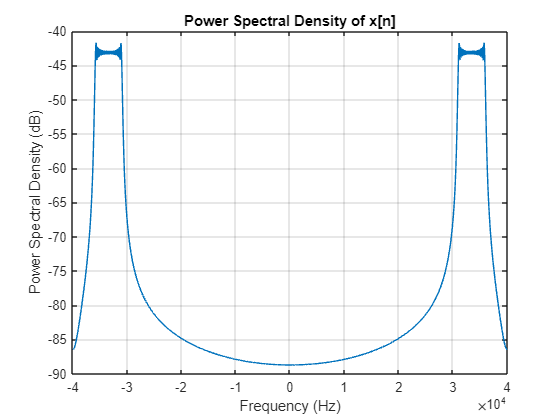

f1 = 4e3;
mu = 100e3;
duration = 50e-3;
fs = 80e3;

t_c = 0:1/fs:duration-(1/fs);
x_c = cos(2*pi*f1*t_c + pi*mu*t_c.^2);

N = 2^12-1;

t_n = 0:(N-1);
x_n = cos(2*pi*f1*t_n/fs + pi*mu*(t_n/fs).^2);

X = fft(x_n);

PSD = (abs(X).^2) / (N * fs);

PSD_dB = 10 * log10(PSD);

frequencies = (-(N-1)/2:(N-1)/2) * fs / N;

figure;
plot(frequencies, PSD_dB);
xlabel('Frequency (Hz)');
ylabel('Power Spectral Density (dB)');
title('Power Spectral Density of x[n]');
grid on;

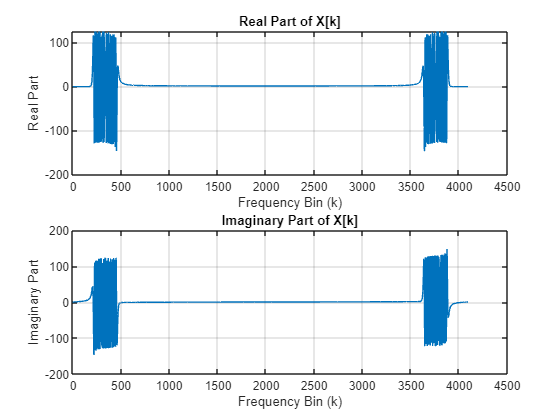

X_shift = fftshift(X);
x_real = real(X_shift);
symmetry_real = rms(x_real-flip(x_real));

x_imag = imag(X_shift);
symmetry_imag = rms(x_imag+flip(x_imag));

figure;
subplot(2,1,1);
plot(t_n, real(X));
xlabel('Frequency Bin (k)');
ylabel('Real Part');
title('Real Part of X[k]');
grid on;

subplot(2,1,2);
plot(t_n, imag(X));
xlabel('Frequency Bin (k)');
ylabel('Imaginary Part');
title('Imaginary Part of X[k]');
grid on;

**The signal X is Hermitian because it is symmetric when flipped across real and imaginary parts.**

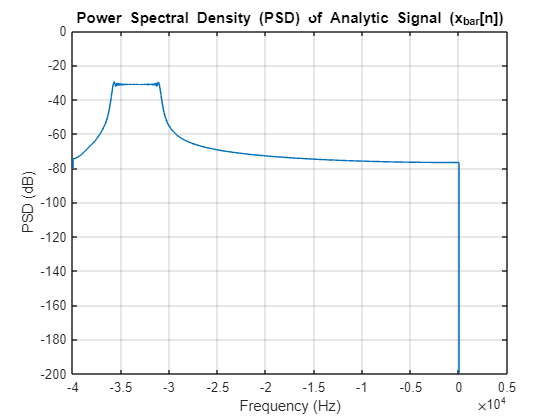

x_bar = hilbert(x_n);
X_bar = fft(x_bar);
PSD_S_bar = (abs(X_bar).^2) / (N * fs);
PSD_bar_dB = 10 * log10(PSD_S_bar)+6;
figure;
plot(frequencies, PSD_bar_dB);
xlabel('Frequency (Hz)');
ylabel('PSD (dB)');
title('Power Spectral Density (PSD) of Analytic Signal (x_{bar}[n])');
grid on;
ylim([-200 0]);

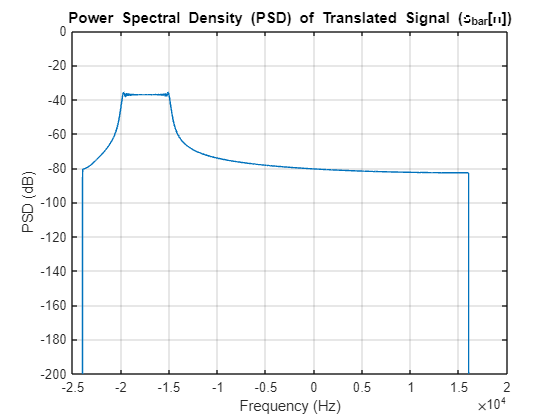

fc = 16e3;

s_bar = x_bar .* exp(1i * 2 * pi * fc / fs * (0:N-1));

S_bar = fft(s_bar);
PSD_S_bar = (abs(S_bar).^2) / (N * fs);
figure;
plot(frequencies, 10 * log10(PSD_S_bar));
xlabel('Frequency (Hz)');
ylabel('PSD (dB)');
title('Power Spectral Density (PSD) of Translated Signal (s_{bar}[n])');
ylim([-200 0]);
grid on;

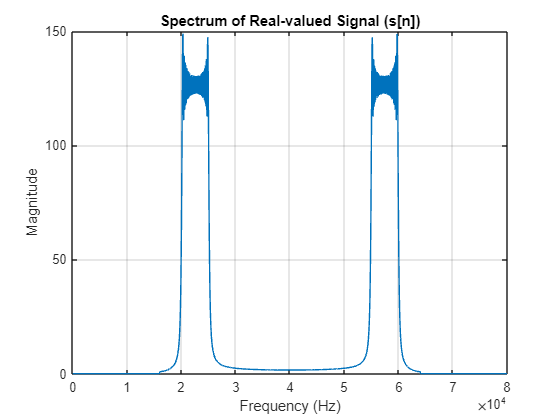

s = real(s_bar);

S = fft(s);
frequencies = (0:N-1) * fs / N;
figure;
plot(frequencies, abs(S));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Spectrum of Real-valued Signal (s[n])');
grid on;

S_shift = fftshift(S);
s_real = real(S_shift);
symmetry_s_real = rms(s_real-flip(s_real));

s_imag = imag(S_shift);
symmetry_s_imag = rms(s_imag+flip(s_imag));


**S is Hermitian because it is symmetric when flipped across real and imaginary parts.**

## TASK 2

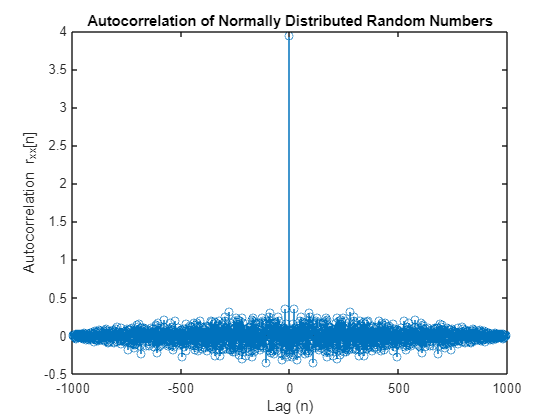

N = 1000;
sigma = 2;
e = sigma * randn(1, N);
[rxx, lag] = xcorr(e, 'biased');
n = -N+1:N-1;
figure;
stem(n, rxx)
xlabel('Lag (n)')
ylabel('Autocorrelation r_{xx}[n]')
title('Autocorrelation of Normally Distributed Random Numbers')

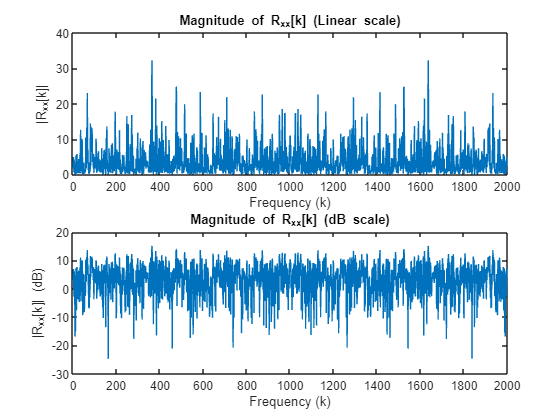

Rxx = fft(rxx);
magnitude_Rxx = abs(Rxx);
magnitude_Rxx_dB = 10*log10(magnitude_Rxx);
figure;
subplot(2, 1, 1);
plot(magnitude_Rxx);
xlabel('Frequency (k)');
ylabel('|R_{xx}[k]|');
title('Magnitude of R_{xx}[k] (Linear scale)');
subplot(2, 1, 2);
plot(magnitude_Rxx_dB);
xlabel('Frequency (k)');
ylabel('|R_{xx}[k]| (dB)');
title('Magnitude of R_{xx}[k] (dB scale)');

mean_Rxx = mean(Rxx);
expected_mean_Rxx = N * sigma^2;
fprintf('Mean of Rxx[k]: %f\n', mean_Rxx);

Mean of Rxx[k]: 0.007676


fprintf('Expected mean of Rxx[k]: %f\n', expected_mean_Rxx);

Expected mean of Rxx[k]: 4000.000000


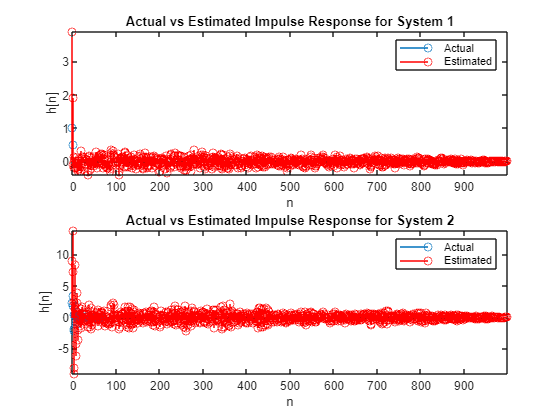

b1 = [1 0.5];
a1 = 1;
h1_n = impz(b1, a1);

b2 = [2.24 2.49 2.24];
a2 = [1 -0.4 0.75];
h2_n = impz(b2, a2);

x_n = e;
y1_n = filter(b1, a1, x_n);
y2_n = filter(b2, a2, x_n); 

[corr_y1x, ~] = xcorr(y1_n, x_n, 'biased');
[corr_y2x, ~] = xcorr(y2_n, x_n, 'biased'); 

est_h1_n = corr_y1x(N:end); 
est_h2_n = corr_y2x(N:end);

figure;
subplot(2, 1, 1);
stem(0:length(h1_n)-1, h1_n);
hold on;
stem(0:length(est_h1_n)-1, est_h1_n, 'r');
title('Actual vs Estimated Impulse Response for System 1');
xlabel('n');
ylabel('h[n]');
legend('Actual', 'Estimated');
axis tight;

subplot(2, 1, 2);
stem(0:length(h2_n)-1, h2_n);
hold on;
stem(0:length(est_h2_n)-1, est_h2_n, 'r');
title('Actual vs Estimated Impulse Response for System 2');
xlabel('n');
ylabel('h[n]');
legend('Actual', 'Estimated');
axis tight;

## Task 3:

 
            fc = 25MHz
            fc = 26.4MHz
            fc = 27.8MHz
            fc = 29.2MHz
            fc = 30.6MHz
            fc = 32MHz
            fc = 33.4MHz
            fc = 34.8MHz
            fc = 36.2MHz
            fc = 37.6MHz
            fc = 39MHz
            fc = 40.4MHz
            fc = 41.8MHz
            fc = 43.2MHz
            fc = 44.6MHz
            fc = 46MHz
            fc = 47.4MHz
            fc = 48.8MHz
            fc = 50.2MHz
            fc = 51.6MHz
            fc = 53MHz
            fc = 54.4MHz
            fc = 55.8MHz
            fc = 57.2MHz
            fc = 58.6MHz
            fc = 60MHz
            fc = 61.4MHz
            fc = 62.8MHz
            fc = 64.2MHz
            fc = 65.6MHz
            fc = 67MHz
            fc = 68.4MHz
            fc = 69.8MHz
            fc = 71.2MHz
            fc = 72.6MHz
            fc = 74MHz
            fc = 75.4MHz
            fc = 76.8MHz
            fc = 78.2MHz
            fc = 79.6MHz
            fc

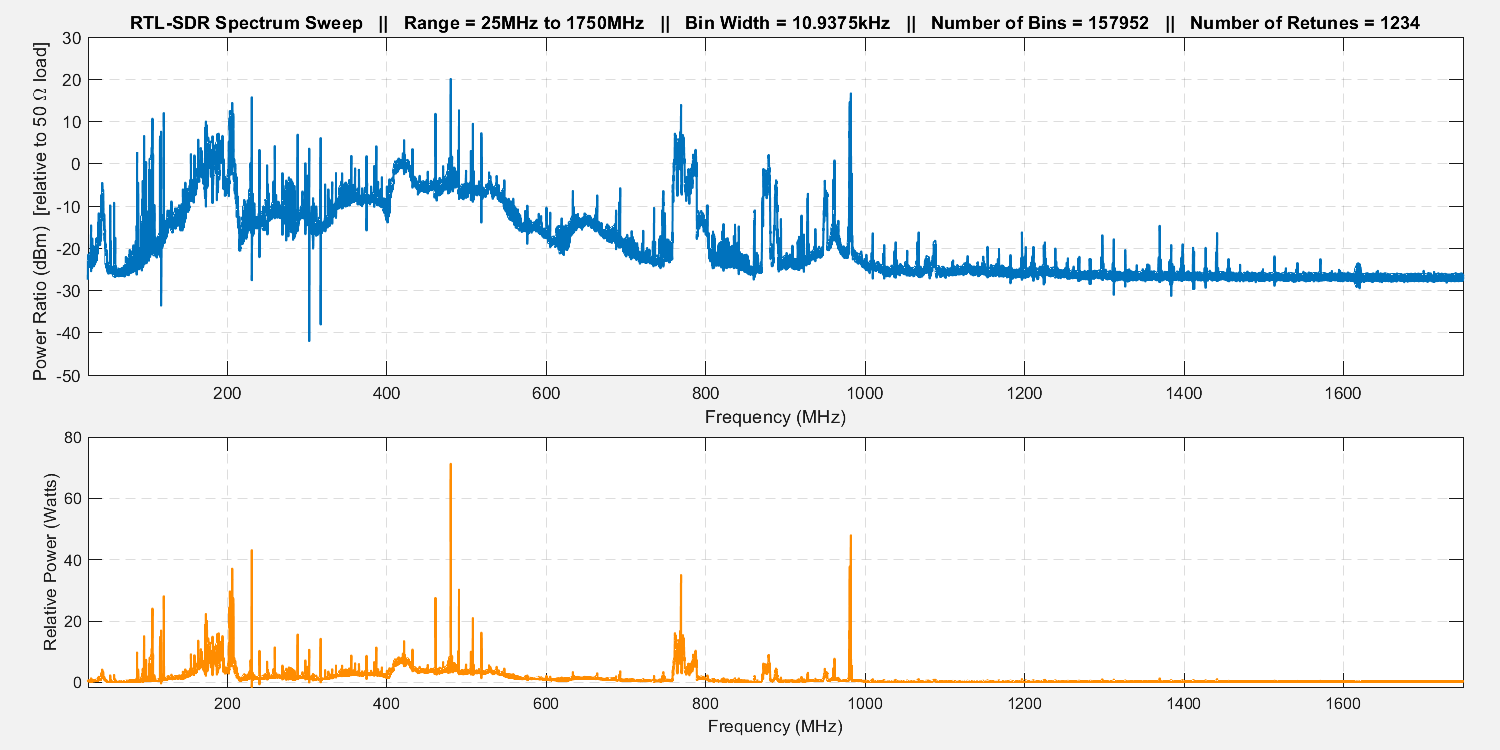

rtlsdr_rx_specsweep();

%% PARAMETERS
rtlsdr_id = '0';
rtlsdr_freq = 96.9e6;
rtlsdr_gain = 40;
rtlsdr_fs = 2.8e6;
rtlsdr_frmLen = 4096;
rtlsdr_datatype = 'single';
rtlsdr_ppm = 0;
sim_time = 60;

obj_rtlsdr = comm.SDRRTLReceiver(...
    'CenterFrequency', rtlsdr_freq,...
    'EnableTunerAGC', false,...
    'TunerGain', rtlsdr_gain,...
    'SampleRate', rtlsdr_fs,...
    'SamplesPerFrame', rtlsdr_frmLen,...
    'OutputDataType', rtlsdr_datatype,...
    'FrequencyCorrection', rtlsdr_ppm);

% spectrum analyzer objects
obj_specfft = dsp.SpectrumAnalyzer(...
    'Name', 'Spectrum Analyzer FFT',...
    'Title', 'Spectrum Analyzer FFT',...
    'SpectrumType', 'Power density',...
    'FrequencySpan', 'Full',...
    'SampleRate', rtlsdr_fs);

obj_specwaterfall = dsp.SpectrumAnalyzer(...
    'Name', 'Spectrum Analyzer Waterfall',...
    'Title', 'Spectrum Analyzer Waterfall',...
    'SpectrumType', 'Spectrogram',...
    'FrequencySpan', 'Full',...
    'SampleRate', rtlsdr_fs);

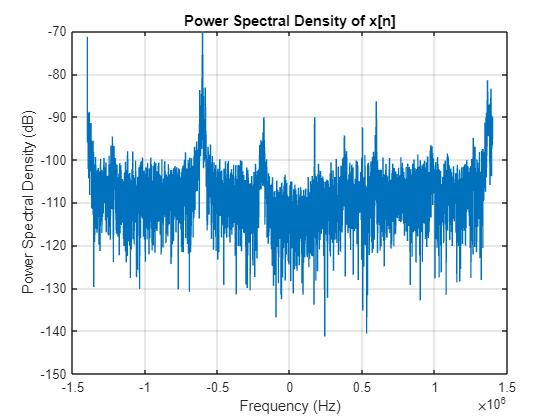


signal = step(obj_rtlsdr);
Signal = fft(signal);

PSD = (abs(Signal).^2) / (rtlsdr_frmLen * rtlsdr_fs);

PSD_dB = 10 * log10(PSD);

frequencies = (-(rtlsdr_frmLen-1)/2:(rtlsdr_frmLen-1)/2) * rtlsdr_fs / rtlsdr_frmLen;

figure;
plot(frequencies, PSD_dB);
xlabel('Frequency (Hz)');
ylabel('Power Spectral Density (dB)');
title('Power Spectral Density of x[n]');
grid on;

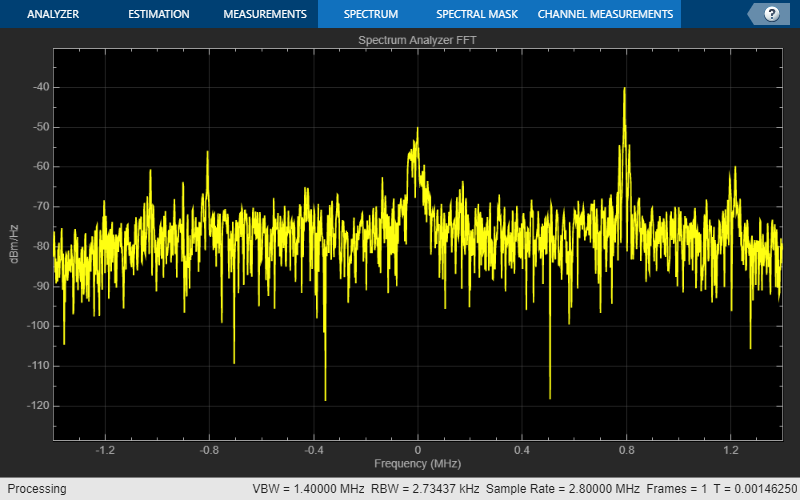

step(obj_specfft, signal);